# Pleasure 2: Spline fits on pleasantness-unpleasantness ratings & BOLD time series data

Purpose: Explore whether spline fits are adequate to capture behavioral valence ratings, and fit them with a spline model.

Here we make a design matrix of (1) 1st C, (2) 2nd C, (3) 1st S, (4) 2nd S of SS, and (5) 2nd S of CS sampled at TR-level.

### Set up paths and load variables

basedir = '/Users/sooahn/Dropbox/2023_SooAhnLee_PainPleasure_TrainingGrant/analyses';

% basedir = '/Users/f003vz1/Dropbox (Dartmouth College)/A1_WORKING_ANALYSES/2023_SooAhnLee_Pain_Pleasure_Training_Grant/analyses';

cd(basedir)

datadir = fullfile(basedir, 'data');
resultsdir = fullfile(basedir, 'results');
scriptsdir = fullfile(basedir, 'scripts');

addpath(scriptsdir)

load(fullfile(datadir, 'continuous_rating_61subjs.mat'));
load(fullfile(datadir, 'condition_colors.mat'));
load(fullfile(datadir, '61subj_index.mat'));

n_sub = numel(subjarray);


**Description of variables:**

rat = ratings, 0 = neutral, -1 = strongest imaginable unpleasantness, 1 = strongest imaginable pleasantness

c0 = capsaicin only

cc = capsaicin twice

cs = caps. then sweet chocolate

ctrl = water only (continuous)

Sampling rate: Ratings are sampled at TR = 0.46 

Events times:

    1.5 min after first sample, 1.5 min * 60 sec * 1/0.46 sampling rate = 196

    7 min after first sample, 7 min * 60 sec * 1/0.46 sampling rate = 913

**Prepare some variables**

TR = 0.46;

evt1 = 196;
evt2 = 913;

tr_len = 1875;

rat_comb = [c0_rat'; cc_rat'; cs_rat'; ss_rat'];

### Plot behavioral ratings

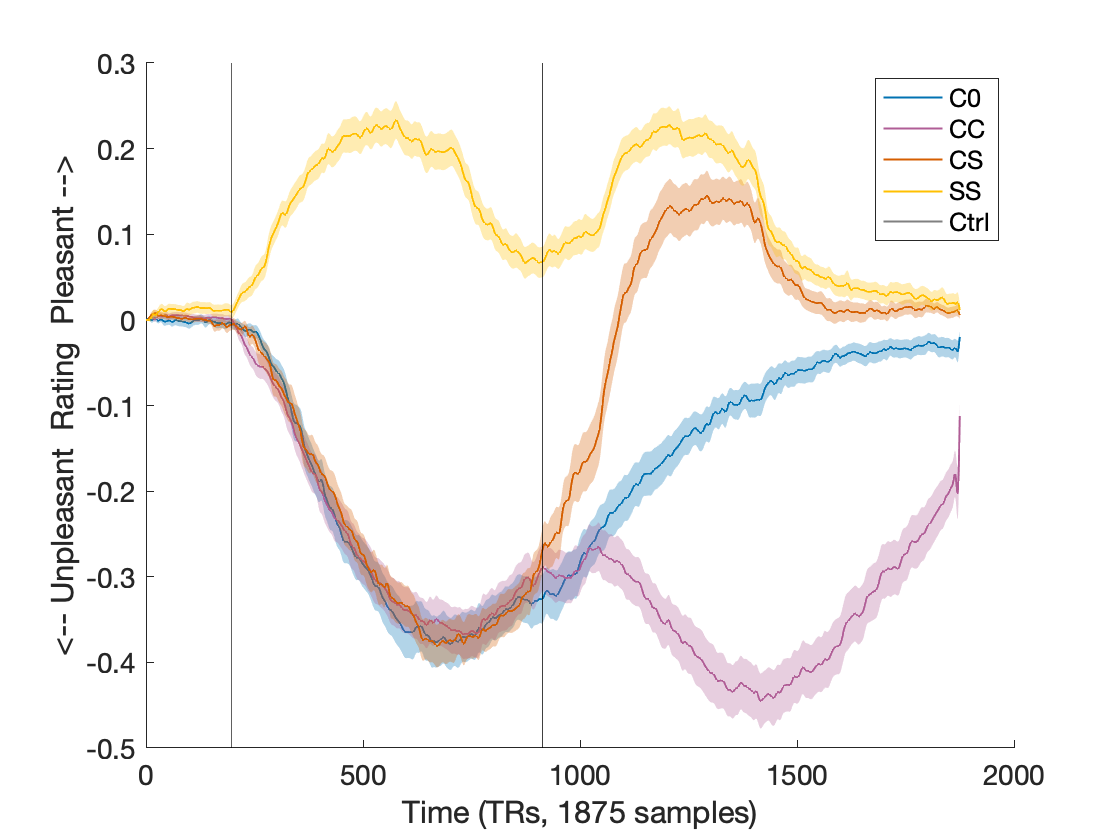

create_figure('ratings');
out1 = lineplot_columns(c0_rat, 'color', c0_col, 'marker', 'none', 'w', 1, 'shade');
out2 = lineplot_columns(cc_rat, 'color', cc_col, 'marker', 'none', 'w', 1, 'shade');
out3 = lineplot_columns(cs_rat, 'color', cs_col, 'marker', 'none', 'w', 1, 'shade');
out4 = lineplot_columns(ss_rat, 'color', ss_col, 'marker', 'none', 'w', 1, 'shade');

ylabel('<-- Unpleasant  Rating  Pleasant -->');
xlabel('Time (TRs, 1875 samples)');

plot_vertical_line(evt1);
plot_vertical_line(evt2);
legend([out1.line_han out2.line_han out3.line_han out4.line_han out5.line_han],'C0','CC','CS','SS','Ctrl');

## Build a design matrix

nBas = 8; % number of basis functions; higher = more spatial resolution. Must be at least k.
k = 4;  % spline order; higher = spline fit curvature matched on more derivatives; 2 = linear; 3 = quadratic; 4 = cubic (default)

For smooth connection between 1st & 2nd events in each condition, we **exclude the last curve of 1st events & first curve in 2nd events**.

Create a set of splines for 'C1' events: **exclude the last curve**

windowlen_c1 = 863-110; % in sec

bf_c1 = Bspline(1:ceil(windowlen_c1 ./ TR),k,[ones(1,k-1) linspace(1,ceil(windowlen_c1 ./ TR)+0.1,nBas-1) (ceil(windowlen_c1 ./ TR)+0.1)*ones(1,k-1)]);
% bf = spm_orth(bf); % orthogonalize bf
bf_c1(:,end) = [];

Create a set of splines for 'C2' events: **exclude the first curve**

windowlen_c2 = 420; % in sec

bf_c2 = Bspline(1:ceil(windowlen_c2 ./ TR),k,[ones(1,k-1) linspace(1,ceil(windowlen_c2 ./ TR)+0.1,nBas-1) (ceil(windowlen_c2 ./ TR)+0.1)*ones(1,k-1)]);
% bf = spm_orth(bf); % orthogonalize bf
bf_c2(:,1) = [];

Create a set of splines for 'S1' events: **exclude the last curve**

windowlen_s1 = 330; % in sec

bf_s1 = Bspline(1:ceil(windowlen_s1 ./ TR),k,[ones(1,k-1) linspace(1,ceil(windowlen_s1 ./ TR)+0.1,nBas-1) (ceil(windowlen_s1 ./ TR)+0.1)*ones(1,k-1)]);
% bf = spm_orth(bf); % orthogonalize bf
bf_s1(:,end) = [];

Create a set of splines for 'S2 of SS' events: **exclude the first curve**

windowlen_s2_ss = 420; % in sec

bf_s2_ss = Bspline(1:ceil(windowlen_s2_ss ./ TR),k,[ones(1,k-1) linspace(1,ceil(windowlen_s2_ss ./ TR)+0.1,nBas-1) (ceil(windowlen_s2_ss ./ TR)+0.1)*ones(1,k-1)]);
% bf = spm_orth(bf); % orthogonalize bf
bf_s2_ss(:,1) = [];

Create a set of splines for 'S2 of CS' events: **exclude the first curve**

windowlen_s2_cs = 420; % in sec

bf_s2_cs = Bspline(1:ceil(windowlen_s2_cs ./ TR),k,[ones(1,k-1) linspace(1,ceil(windowlen_s2_cs ./ TR)+0.1,nBas-1) (ceil(windowlen_s2_cs ./ TR)+0.1)*ones(1,k-1)]);
% bf = spm_orth(bf); % orthogonalize bf
bf_s2_cs(:,1) = [];


names = {'Capsaicin1' 'Capsaicin2' 'Sweet1' 'Sweet2_Sweet' 'Sweet2_Caps'};

total_len = tr_len * 8;


% c1
ons = {};
ons{1} = [evt1 evt1 + tr_len*2 evt1 + tr_len*4]'; % including a dummy run every other run


% Design matrix has concatenated runs
X_c1 = onsets2fmridesign(ons, 1, total_len, bf_c1);


% c2
ons = {};
ons{1} = [evt2 + tr_len*2];


% Design matrix has concatenated runs
X_c2 = onsets2fmridesign(ons, 1, total_len, bf_c2);


% s1
ons = {};
ons{1} = [evt1 + tr_len*6];


X_s1 = onsets2fmridesign(ons, 1, total_len, bf_s1);


% s2_ss
ons = {};
ons{1} = [evt2 + tr_len*6];


X_s2_ss = onsets2fmridesign(ons, 1, total_len, bf_s2_ss);


% s2_cs
ons = {};
ons{1} = [evt2 + tr_len*4];


X_s2_cs = onsets2fmridesign(ons, 1, total_len, bf_s2_cs);


% concat
X = [X_c1 X_c2 X_s1 X_s2_ss X_s2_cs];

wh_dummy = [1+tr_len:tr_len*2 1+tr_len*3:tr_len*4 1+tr_len*5:tr_len*6 1+tr_len*7:tr_len*8];
X(wh_dummy,:) = [];

vif = getvif(X,0);


X = [X blkdiag(ones(tr_len,1),ones(tr_len,1),ones(tr_len,1),ones(tr_len,1))];


figure; plot_matrix_cols(X)

ans =   1×49 Line array:

  Columns 1 through 44

    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line

  Columns 45 through 49

    Line    Line    Line    Line    Line


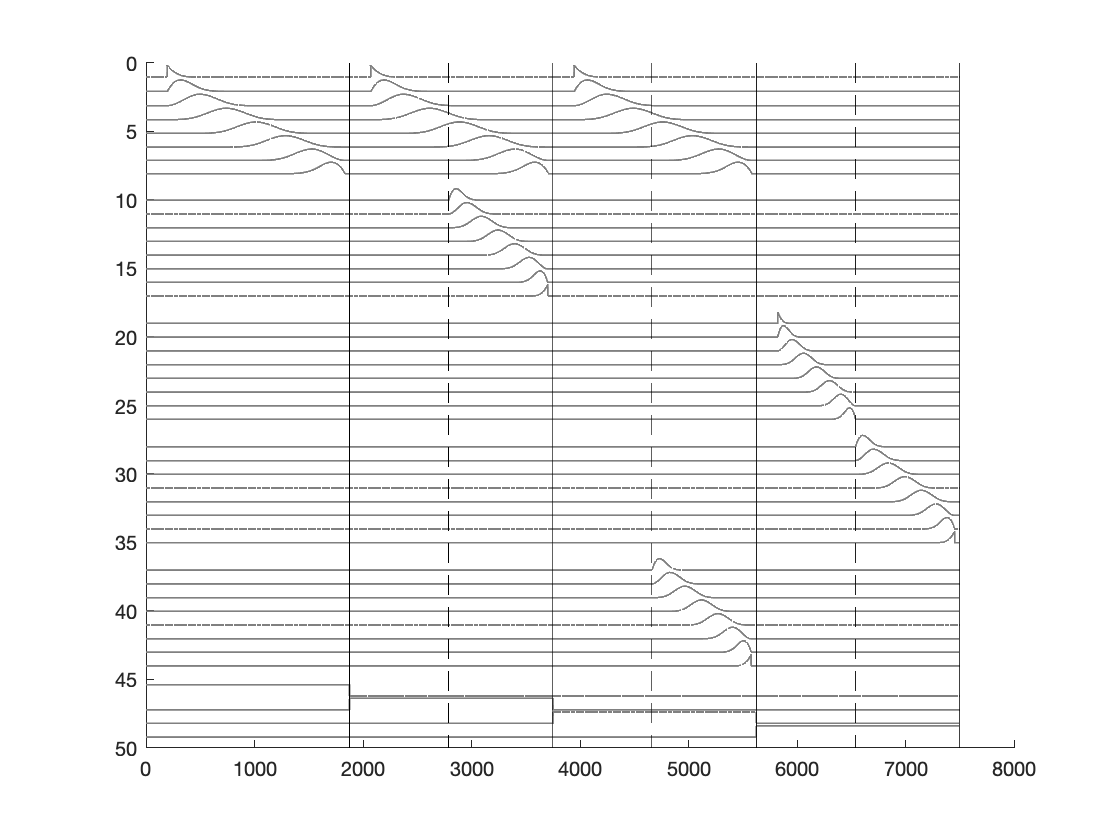

plot_vertical_line(tr_len);
hh = plot_vertical_line(tr_len+evt2); set(hh, 'LineStyle', '--');
plot_vertical_line(tr_len*2);
hh = plot_vertical_line(tr_len*2+evt2); set(hh, 'LineStyle', '--');
plot_vertical_line(tr_len*3);
hh = plot_vertical_line(tr_len*3+evt2); set(hh, 'LineStyle', '--');
plot_vertical_line(tr_len*4);

### Save

% save(fullfile(datadir,'design_matrix_trlevel.mat'),'X','bf*');